%R=4 and d=10 give some beautiful results 

%First the model is simulated to obtained some 
%Data which can be utilized by the HAVOK 
clear
simTimEnd=100;
samplingTime=0.01;

%Genertaing inital value of state x1 and x2
%In general, you can generate N
%random numbers in the interval (a,b) 
% with the formula r = a + (b-a).*rand(N,1).
a=-2;
b=2;

x1=a+(b-a)*rand();
x2=a+(b-a)*rand();

%Generating/Simulation some data to work with:

index=1; %Index to save some numbers 

for i=0:samplingTime:simTimEnd
    %The contious time model: 
    x1dot=2*x2(index,1);
    x2dot=-0.8*x1(index,1)+2*x2(index,1)-10*x1(index,1)^2*x2(index,1);
    
   %Using forward euler to get the states value: 
    index=index+1; 
    x1(index,1)=x1dot*samplingTime+x1(index-1,1);
    x2(index,1)=x2dot*samplingTime+x2(index-1,1);
end
    %Collecting all measured data into one matrix
    xAll=[x1';x2'];


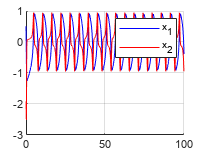

%Plotting the generated data:
time=0:samplingTime:simTimEnd+samplingTime; 

hold on 
plot(time,x1,'blue')
plot(time,x2,'red')
hold off 
grid
legend('x_1','x_2')

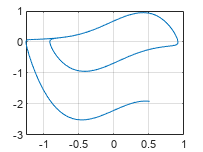



plot(x1,x2)
grid

%Making the Hankel matrix, which will be based on 5000 points, and a delay
%of 50 

d=50; 
n=size(xAll,1); %Determine the amount of states 
m=5000;
index=1;
for i=0:d
    H(index:index+n-1,:)=xAll(:,d-i+1:m-i);
    index=index+n;
end

%Takning the SVD of the Hankel matirx 
[U,S,V]=svd(H);



%Making the short version of the matrixs another group found that 12 
%is perfect. However, this result in a high condition number
%Therefore R=6 is ultizied

    R=6; % Truncation valuve 12 in the report, but gives a high condition number 
    % therefore a truncation valvue of 6 is utilized.  
    
    Vr=V(:,1:R);
    Sr=S(1:R,1:R);
    Ur=U(:,1:R);
    
    %Checking if the condition number is okay
    cond(Sr)

ans = 106.6754


    %Making Pdown:
    Pdown=pinv(Ur*Sr);
    %Making Pup:
    Pup=(Ur*Sr);
  
    
    %Making the concurrent and predict V based on the small V
    VrCon=Vr(1:end-1,:);
    VrPred=Vr(2:end,:);
   

    %Approximation A:
    %A=transpose(Vtildepred)*pinv(transpose(VtildeCon));
    Av=transpose(VrPred)*pinv(transpose(VrCon))

Av =     1.0000   -0.0118    0.0002    0.0008    0.0000   -0.0002
    0.0126    0.9977   -0.0174   -0.0007   -0.0026    0.0000
    0.0006    0.0142    0.9975   -0.0477    0.0004    0.0074
   -0.0023    0.0105    0.0539    0.9868   -0.0610    0.0020
    0.0011   -0.0035   -0.0023    0.0742    0.9860    0.1151
   -0.0021    0.0130    0.0010   -0.0357   -0.0907    0.9684



  
    
    %The times series which is project to V, needs to have the same amout
    %of rows as H, as a delay of 50 was used and 2 states is present which
    %corresponds to 100 rows, therefore 99 present and the current sample
    %is used. The "model" was train on data from 0 to 5049, therefore the 
    % time series starts at 4951 to 5050 and builds up to 10000



    %To only pickout the predited output instead of the entire sequences
    ny=2;
    Cc=[1,zeros(1,ny*(d+1)-1);0,1,zeros(1,ny*(d+1)-2)];
for i=1:5000
    %Taking out the 100 samples
    %Hr=flip(xAll(:,5000-(d+1)*ny+i:5000+i-1),2);
    clear Hr;
    index=1;
    for j=d+i:-1:i
        Hr(index:index+n-1,:)=xAll(:,5000-d+j);
        index=index+n;
    end

    %Projecting to the V subspace: 
    vk=Pdown*Hr; 

    %Making prediction:
    vkPred=Av*vk; 

    %Transforming the prediction back to the state space representation
    PreditionX=Pup*vkPred;

    %Only takning out the newest/predict value of x, and forgetting the
    %rest of the time series ;D 
    
    PredictionXsave(:,i)=Cc*PreditionX;
    %PredictionXsave(:,i)=PreditionX'*Cc;
end 

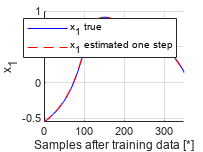

%Making plots of the estimation and the true simulated values for one step
%esitmation

time2=0:samplingTime:simTimEnd/2-51*samplingTime;
clf
hold on 
plot(x1(5001:10000,1),'blue')
plot(PredictionXsave(1,:),'--r')
hold off 
grid
legend('x_1 true','x_1 estimated one step')
xlabel("Samples after training data [*]")
ylabel('x_1')
ax=gca;
xlim([0 350])
exportgraphics(ax,"x1_HAVOK_no_input.pdf")

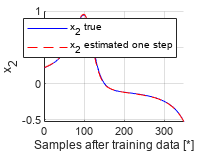



clf
hold on 
plot(x2(5001:10000,1),'blue')
plot(PredictionXsave(2,:),'--r')
hold off 
grid
legend('x_2 true','x_2 estimated one step')
xlabel("Samples after training data [*]")
ylabel('x_2')
xlim([0 350])

ax=gca;
exportgraphics(ax,"x2_HAVOK_no_input.pdf")

%Now trying with to preditec only based on the training data 
clear Hr 
i=1; 
index=1;
    for j=d+i:-1:i
        Hr(index:index+n-1,:)=xAll(:,5000-d+j);
        index=index+n;
    end

for i=1:5000-d

    %Projecting to the V subspace: 
    vk=Pdown*Hr; 

    %Making prediction:
    vkPred=Av*vk; 

    %Transforming the prediction back to the state space representation
    PreditionX=Pup*vkPred;

    %Only takning out the newest/predict value of x, and forgetting the
    %rest of the time series ;D 

    PredictionXsaveMulti(:,i)=Cc*PreditionX;
    %Updating xdata
    Hr=[Cc*PreditionX; Hr(1:end-n)];

end 

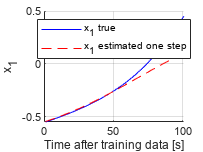

%Comparing the multiple prediction step to the real value of the states
clf
hold on 
plot(x1(5001:5101,1),'blue')
plot(PredictionXsaveMulti(1,1:100),'--r')
hold off 
grid
legend('x_1 true','x_1 estimated one step','location','best')
xlabel("Time after training data [s]")
ylabel('x_1')
ax=gca;
exportgraphics(ax,"x1_HAVOK_no_input_multi.pdf")

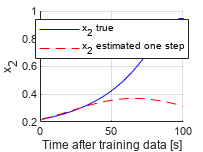



clf
hold on 
plot(x2(5001:5101,1),'blue')
plot(PredictionXsaveMulti(2,1:100),'--r')
hold off 
grid
legend('x_2 true','x_2 estimated one step','location','best')
xlabel("Time after training data [s]")
ylabel('x_2')

ax=gca;
exportgraphics(ax,"x2_HAVOK_no_input_multi.pdf")